clear all;

rng(123456);

xs = -0.2:0.01:1.2;
xs = xs';
ff = @(xx) 5*xx.^2.*sin(12*xx) + (xx.^3-0.5).*sin(3*xx-0.5)+4*cos(2*xx);
ys = ff(xs);

xnorm = 1; ynorm = 1; % whether use normalization
yns = 0.5; % noise scale

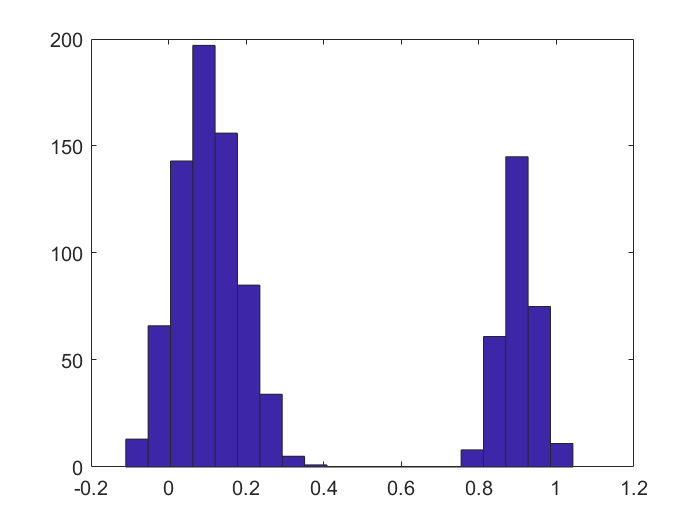

n = 1e3; % size of training data
dcs = 100; % size of the communication set
m = round(n / dcs); % m is the number of experts
lp = 0.7; lc = 0.1; rc = 0.9;
sig1 = 0.08; sig2 = 0.05;
testsize = 500; % size of test data
induce_step = 100;

% training input
ori_all_trainxs = [sig1*randn(round(n*lp), 1) + lc; sig2*randn(round(n*(1-lp)), 1) + rc];

% figure;
% plot(ori_all_trainxs, zeros(n, 1), 'b.');
figure;
hist(ori_all_trainxs,20);
set(gca,'FontSize',12)

% test input
ori_testxs = [sig1*randn(round(testsize*lp), 1) + lc; sig2*randn(round(testsize*(1-lp)), 1) + rc];


% ininput normalization
if xnorm == 1
    norm_xmean = mean(ori_all_trainxs);
    norm_xstd = std(ori_all_trainxs);
    all_trainxs = (ori_all_trainxs - norm_xmean) / norm_xstd;
    
    testxs = (ori_testxs - norm_xmean) / norm_xstd;
    xs_ax = (xs - norm_xmean) / norm_xstd;
else
    all_trainxs = ori_all_trainxs;
    testxs = ori_testxs;
end

% training output
ln = length(all_trainxs);
xvec = all_trainxs; ori_xvec = ori_all_trainxs;
ori_yvec = ff(ori_all_trainxs) + yns*randn(ln, 1);

% test output
ln = length(testxs);
xvec_test = testxs; ori_xvec_test = ori_testxs;
ori_yvec_test = ff(ori_testxs) + yns*randn(ln, 1);

% output normalization
if ynorm == 1
    norm_fmean = mean(ori_yvec);
    norm_fstd = std(ori_yvec);
    yvec = (ori_yvec - norm_fmean) / norm_fstd;
    yvec_test = (ori_yvec_test - norm_fmean) / norm_fstd;
else
    yvec = ori_yvec;
    yvec_test = ori_yvec_test;
end

sf2 = 1 ; ell = 1 ; sn2 = 0.1 ; 
d = size(xvec,2);
hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];
opts.Xnorm = 'N' ; opts.Ynorm = 'N' ;
opts.Ms = 5 ;
opts.ell = ell ; opts.sf2 = sf2 ; opts.sn2 = sn2 ;
opts.meanfunc = []; opts.covfunc = @covSEard; opts.likfunc = @likGauss; opts.inffunc = @infGaussLik ;
opts.induce_step = induce_step ;

x = xvec; y = yvec;
xt = xvec_test; yt = yvec_test;

meanfunc = [];                    % empty: don't use a mean function
covfunc = opts.covfunc;              % Squared Exponental covariance function
likfunc = opts.likfunc;              % Gaussian likelihood
inffunc = opts.inffunc;

hyp2 = minimize(hyp, @gp, -50, inffunc, meanfunc, covfunc, likfunc, x, y)

Function evaluation      0;  Value -3.049001e+02
Function evaluation      8;  Value -5.697030e+02
Function evaluation     10;  Value -5.866139e+02
Function evaluation     12;  Value -5.936184e+02
Function evaluation     14;  Value -5.955537e+02
Function evaluation     17;  Value -5.956535e+02
Function evaluation     19;  Value -5.956609e+02
Function evaluation     21;  Value -5.956648e+02
Function evaluation     23;  Value -5.956673e+02
Function evaluation     26;  Value -5.956763e+02
Function evaluation     28;  Value -5.956889e+02
Function evaluation     30;  Value -5.957231e+02
Function evaluation     31;  Value -5.957548e+02
Function evaluation     33;  Value -5.957750e+02
Function evaluation     35;  Value -5.958031e+02
Function evaluation     38;  Value -5.958036e+02
Function evaluation     40;  Value -5.958037e+02
Function evaluation     43;  Value -5.958037e+02
Function evaluation     48;  Value -5.958041e+02


hyp2 = 包含以下字段的 struct :
     cov: [2×1 double]
     lik: -2.0434
    mean: []


[fgtmu, fgts2] = gp(hyp2, @infGaussLik, meanfunc, covfunc, likfunc, x, y, xs_ax);
if ynorm==1 % normalize predictive output
    fgmu = fgtmu * norm_fstd + norm_fmean;
    fgs2 = fgts2 * norm_fstd^2;
end

fgarea = [fgmu+2*sqrt(fgs2); flipdim(fgmu-2*sqrt(fgs2),1)];

ki = 1;
km_iters = 1e4; induce_iters = 200;
grls = 0.7:0.05:1.0;

n_per = dcs ; % size of Dc
Indics = randperm(n) ;
I_com = Indics(1:n_per) ; % randomly select communication set
[idx, C] = kmeans(xvec, m,'MaxIter',km_iters);    

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 50 ;
opts.Ms = m+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.induce_size = dcs;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
opts.I_com = I_com;
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, xvec(I_com,:)};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

g_opts = opts;
g_opts.compute_hyp = 1;
g_opts.grbcm_baseline = 1;
g_opts.global_index = ones(n,1);
g_models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); 

Optimizing hyps in training...
Linesearch      0;  Value -7.669288e+01
Linesearch      1;  Value -4.943660e+02
Linesearch      2;  Value -5.400122e+02
Linesearch      3;  Value -5.403152e+02
Linesearch      4;  Value -5.434492e+02
Linesearch      5;  Value -5.436049e+02
Linesearch      6;  Value -5.437103e+02
Linesearch      7;  Value -5.437105e+02
Linesearch      8;  Value -5.437108e+02
Linesearch      9;  Value -5.437108e+02
Linesearch     10;  Value -5.437109e+02
Linesearch     11;  Value -5.437109e+02
Linesearch     12;  Value -5.437109e+02
Linesearch     13;  Value -5.437109e+02
Linesearch     14;  Value -5.437109e+02
Linesearch     15;  Value -5.437109e+02
Linesearch     16;  Value -5.437109e+02
Linesearch     17;  Value -5.437109e+02
Linesearch     18;  Value -5.437109e+02
Linesearch     19;  Value -5.437109e+02
Linesearch     20;  Value -5.437109e+02


opts.hyp = g_models{1}.hyp;
g_opts.hyp = g_models{1}.hyp;
[tmu,ts2, ~] =  aggregation_predict(xvec_test,g_models,'GRBCM', 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[grbcmMSE,grbcmSMSE,grbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM', n_per, grbcmMSE,grbcmSMSE,grbcmMSLL);

GRBCM (Dc size 100): MSE 0.24191182, SMSE 0.01677776, MSLL -2.04161032


% grbcm0_smse_rec(ki) = grbcmSMSE; grbcm0_msll_rec(ki) = grbcmMSLL;
g_opts.compute_hyp = 0;


% % VFE Baseline
vfe_opts = opts;
vfe_opts.induce_type = 'VFE_opt';
xu = xvec(I_com, :);
inffunc = @(varargin) infGaussLik(varargin{:}, struct('s', 0.0));
vfe_hyp = opts.hyp;
vfe_hyp.xu = xu;
vfe_hyp = minimize(vfe_hyp,@sp_gp,-vfe_opts.induce_step,inffunc,meanfunc,covfuncF,likfunc,xvec,yvec);

Function evaluation      0;  Value -5.952378e+02
Function evaluation      2;  Value -5.952577e+02
Function evaluation      4;  Value -5.952598e+02
Function evaluation      7;  Value -5.952599e+02
Function evaluation     10;  Value -5.952600e+02
Function evaluation     13;  Value -5.952602e+02
Function evaluation     15;  Value -5.952602e+02
Function evaluation     17;  Value -5.952603e+02
Function evaluation     20;  Value -5.952604e+02
Function evaluation     24;  Value -5.952604e+02
Function evaluation     25;  Value -5.952604e+02
Function evaluation     27;  Value -5.952604e+02
Function evaluation     29;  Value -5.952605e+02
Function evaluation     31;  Value -5.952605e+02
Function evaluation     32;  Value -5.952605e+02
Function evaluation     34;  Value -5.952605e+02
Function evaluation     38;  Value -5.952605e+02
Function evaluation     40;  Value -5.952605e+02
Function evaluation     42;  Value -5.952605e+02
Function evaluation     44;  Value -5.952605e+02
Function evaluation 

vfe_opts.hyp = opts.hyp;
vfe_opts.xu = vfe_hyp.xu;
vfe_opts.inffunc = @infGaussLik; vfe_opts.meanfunc = meanfunc; vfe_opts.covfuncF = covfuncF; vfe_opts.likfunc = likfunc;
vfe_opts.covfunc = covfunc;
[tmu, ts2] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, xvec_test);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[vfeMSE,vfeSMSE,vfeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'VFE baseline', n_per, vfeMSE,vfeSMSE,vfeMSLL);

VFE baseline (Dc size 100): MSE 0.23473806, SMSE 0.01628022, MSLL -2.06011771


% vfe0_smse_rec(ki) = vfeSMSE; vfe0_msll_rec(ki) = vfeMSLL;
[yu, su] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, vfe_opts.xu);
vfe_opts.yu = yu; vfe_opts.su = su; 

sp_opts = opts;
sp_opts.induce_type = 'SPGP_opt';
hyp_init(1:d,1) = -2*opts.hyp.cov(1:d);
hyp_init(d+1,1) = 2*opts.hyp.cov(d+1);
hyp_init(d+2,1) = 2*opts.hyp.lik;

xu = xvec(I_com, :);
w_init = [reshape(xu,sp_opts.induce_size*d,1);hyp_init];
[w,f] = minimize(w_init,'spgp_lik_nohyp',-sp_opts.induce_step,yvec,xvec,sp_opts.induce_size);

Function evaluation      0;  Value -5.952606e+02
Function evaluation      8;  Value -5.952908e+02
Function evaluation     13;  Value -5.954218e+02
Function evaluation     16;  Value -5.954637e+02
Function evaluation     18;  Value -5.955383e+02
Function evaluation     20;  Value -5.956093e+02
Function evaluation     22;  Value -5.957196e+02
Function evaluation     24;  Value -5.957950e+02
Function evaluation     26;  Value -5.959084e+02
Function evaluation     28;  Value -5.959714e+02
Function evaluation     30;  Value -5.960102e+02
Function evaluation     32;  Value -5.960516e+02
Function evaluation     34;  Value -5.960637e+02
Function evaluation     37;  Value -5.960642e+02
Function evaluation     42;  Value -5.960684e+02
Function evaluation     43;  Value -5.960708e+02
Function evaluation     46;  Value -5.960794e+02
Function evaluation     49;  Value -5.960862e+02
Function evaluation     52;  Value -5.960969e+02
Function evaluation     54;  Value -5.960994e+02
Function evaluation 

xb = reshape(w(1:sp_opts.induce_size*d,1),sp_opts.induce_size,d);
sp_opts.xu = xb;
sp_opts.sp_hyp = w(sp_opts.induce_size*d+1:end,1);
sp_opts.hyp = opts.hyp;

[tmu,ts2] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,xvec_test,sp_opts.sp_hyp);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[spgpMSE,spgpSMSE,spgpMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'SPSG baseline', n_per, spgpMSE,spgpSMSE,spgpMSLL);

SPSG baseline (Dc size 100): MSE 0.23516306, SMSE 0.01630970, MSLL -2.05624866


% spgp0_smse_rec(ki) = spgpSMSE; spgp0_msll_rec(ki) = spgpMSLL;
[yu,su] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,sp_opts.xu,sp_opts.sp_hyp);
sp_opts.yu = yu; sp_opts.su = su;

for i=1:5
    [tmu,ts2] = gp(g_opts.hyp,g_opts.inffunc,g_opts.meanfunc, ...
                   g_opts.covfunc,g_opts.likfunc, ...,
                   g_models{i}.X,g_models{i}.Y,xs_ax);
    if ynorm==1 % normalize predictive output
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
        tmpx = g_models{i}.X * norm_xstd + norm_xmean;
        tmpy = g_models{i}.Y * norm_fstd + norm_fmean;        
    end
%     figure; hold on; 
%     f = [tmu+2*sqrt(ts2); flipdim(tmu-2*sqrt(ts2),1)];
%     fill([xs; flipdim(xs,1)], f, [7 7 7]/8)
%     plot(xs, tmu, 'r'); plot(tmpx, tmpy, 'b.');
% %     plot(xs, tmu+2*sqrt(ts2)); plot(xs, tmu-2*sqrt(ts2));
%     plot(xs, ys, 'g');
end

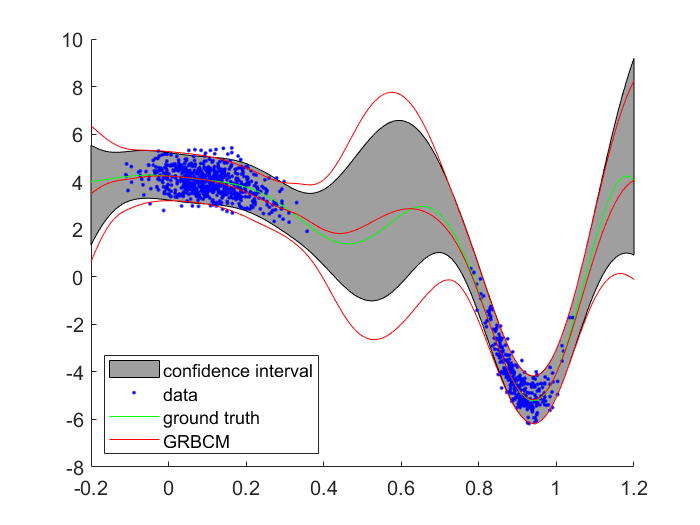

criterion = 'GRBCM';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xs_ax,g_models,criterion, 1,opts);
if ynorm==1 % normalize predictive output
    tmu0 = tmu * norm_fstd + norm_fmean;
    ts20 = ts2 * norm_fstd^2;
end
figure; hold on; 
f = [tmu0+2*sqrt(ts20); flipdim(tmu0-2*sqrt(ts20),1)];
fill([xs; flipdim(xs,1)], fgarea, [5 5 5]/8)
plot(ori_xvec, ori_yvec, 'b.');
plot(xs, ys, 'g'); 
plot(xs, tmu0, 'r', xs, tmu0+2*sqrt(ts20), 'r', xs, tmu0-2*sqrt(ts20), 'r');
lgd = legend('confidence interval', 'data', 'ground truth', 'GRBCM');
lgd.Location = 'southwest';
set(gca,'FontSize',12)

% compute informatic importance
ds = zeros(n, m);
for i=1:n
    for j=1:m
        %ds(i,j) = muti1(i)-muti2(j,i)+muti1(j)-muti2(i,j);
        ds(i,j) = norm(xvec(i, :) - C(j,:));
    end
end
% 1st closest cluster centers
[~, fcc] = min(ds, [], 2);
% set to inf
for i=1:n
    ds(i, fcc(i)) = 1e10;
end
% 2st closest cluster centers
[~, scc] = min(ds, [], 2);
rk = zeros(n, 1);
models = g_models;
for iik=1:n
    i = fcc(iik);
    [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
        covfunc,likfunc,models{i+1}.X,models{i+1}.Y,xvec(iik,:));
    h1 = 0.5*log(tmp_sig2);
    j = scc(iik);
    [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
        covfunc,likfunc,[models{i+1}.X;models{j+1}.X],[models{i+1}.Y;models{j+1}.Y],xvec(iik,:));
    h2 = 0.5*log(tmp_sig2);
    rk(iik) = h2 - h1; % importance is the difference between mutual information
end

gr=1.0

gr = 1

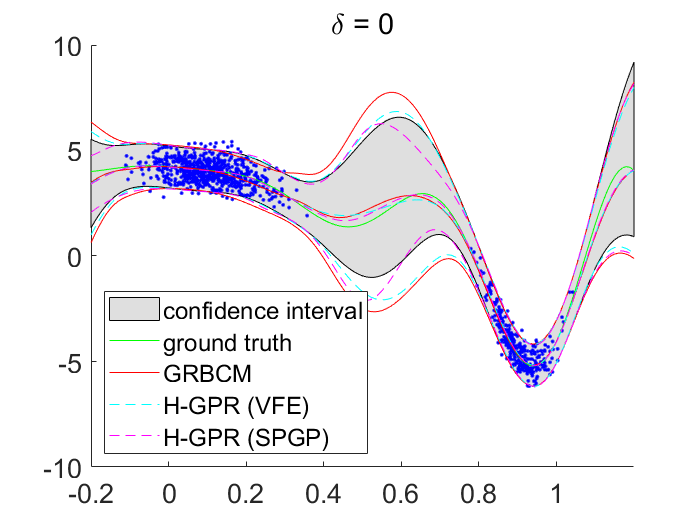


crk = rk;
crk(I_com) = -1e10;
[~, crk_idx] = sort(crk, 'descend');
rn = round(n*gr);
global_index = zeros(n,1);
global_index(crk_idx(1:rn)) = 1; % select remaining data according to the importance

% only remove data from subsets, in RBGCM
g_opts.global_index = global_index;
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xs_ax,models,g_opts);
if ynorm==1
    tmuor = tmu * norm_fstd + norm_fmean;
    ts2or = ts2 * norm_fstd^2;
end

% remove data, and use sparse approximation
vfe_opts.global_index = global_index;
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xs_ax,models,vfe_opts);
if ynorm==1
    vfetmu = tmu * norm_fstd + norm_fmean;
    vfets2 = ts2 * norm_fstd^2;
end

sp_opts.global_index = global_index;
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xs_ax,models,sp_opts);
if ynorm==1
    sptmu = tmu * norm_fstd + norm_fmean;
    spts2 = ts2 * norm_fstd^2;
end

figure; hold on; 
h1 = fill([xs; flipdim(xs,1)], fgarea, [7 7 7]/8);
h2 = plot(ori_xvec, ori_yvec, 'b.');
h3 = plot(xs, ys, 'g'); 
h4 = plot(xs, tmu0, 'r'); plot(xs, tmu0+2*sqrt(ts20), 'r', xs, tmu0-2*sqrt(ts20), 'r-');
h6 = plot(xs, vfetmu, 'c--'); plot(xs, vfetmu+2*sqrt(vfets2), 'c--', xs, vfetmu-2*sqrt(vfets2), 'c--');
h7 = plot(xs, sptmu, 'm--'); plot(xs, sptmu+2*sqrt(spts2), 'm--', xs, sptmu-2*sqrt(spts2), 'm--');

legend([h1,h3,h4,h6,h7], ...
    {'confidence interval', 'ground truth', ...
    'GRBCM', 'H-GPR (VFE)', 'H-GPR (SPGP)'}, ...
    "Location", "southwest")
title('\delta = 0');
xlim([-0.2, 1.2])
set(gca,'FontSize',16)

gr=0.7

gr = 0.7000

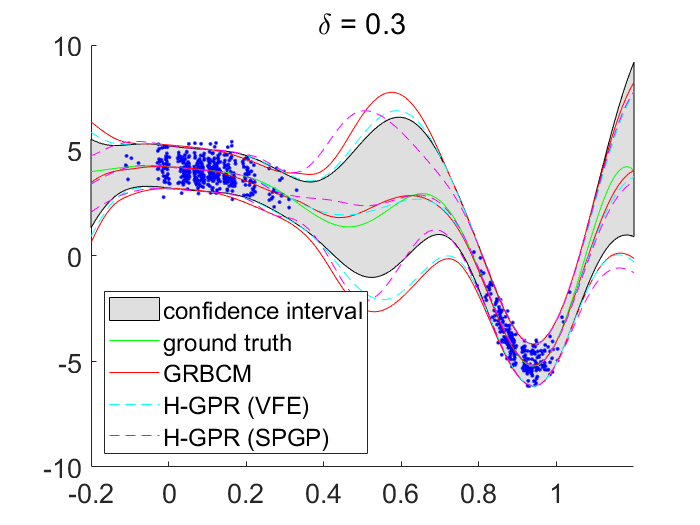


crk = rk;
crk(I_com) = -1e10;
[~, crk_idx] = sort(crk, 'descend');
rn = round(n*gr);
global_index = zeros(n,1);
global_index(crk_idx(1:rn)) = 1; % select remaining data according to the importance

% only remove data from subsets, in RBGCM
g_opts.global_index = global_index;
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xs_ax,models,g_opts);
if ynorm==1
    tmuor = tmu * norm_fstd + norm_fmean;
    ts2or = ts2 * norm_fstd^2;
end

% remove data, and use sparse approximation
vfe_opts.global_index = global_index;
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xs_ax,models,vfe_opts);
if ynorm==1
    vfetmu = tmu * norm_fstd + norm_fmean;
    vfets2 = ts2 * norm_fstd^2;
end

sp_opts.global_index = global_index;
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xs_ax,models,sp_opts);
if ynorm==1
    sptmu = tmu * norm_fstd + norm_fmean;
    spts2 = ts2 * norm_fstd^2;
end

figure; hold on; 
h1 = fill([xs; flipdim(xs,1)], fgarea, [7 7 7]/8);
h2 = plot(ori_xvec(crk_idx(1:rn)), ori_yvec(crk_idx(1:rn)), 'b.');
h3 = plot(xs, ys, 'g'); 
h4 = plot(xs, tmu0, 'r'); plot(xs, tmu0+2*sqrt(ts20), 'r', xs, tmu0-2*sqrt(ts20), 'r-');
h6 = plot(xs, vfetmu, 'c--'); plot(xs, vfetmu+2*sqrt(vfets2), 'c--', xs, vfetmu-2*sqrt(vfets2), 'c--');
h7 = plot(xs, sptmu, 'm--'); plot(xs, sptmu+2*sqrt(spts2), 'm--', xs, sptmu-2*sqrt(spts2), 'm--');

legend([h1,h3,h4,h6,h7], ...
    {'confidence interval', 'ground truth', ...
    'GRBCM', 'H-GPR (VFE)', 'H-GPR (SPGP)'}, ...
    "Location", "southwest")
title('\delta = 0.3');
xlim([-0.2, 1.2])
set(gca,'FontSize',16)

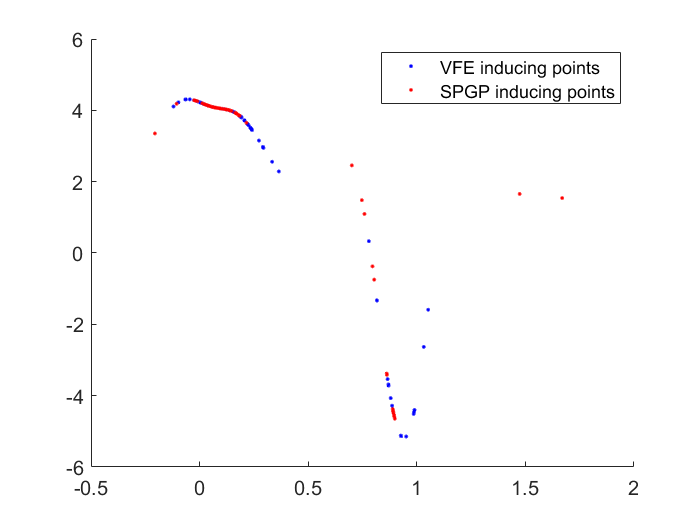

figure; hold on;
plot(vfe_opts.xu*norm_xstd+norm_xmean, vfe_opts.yu*norm_fstd+norm_fmean, 'b.');
plot(sp_opts.xu*norm_xstd+norm_xmean, sp_opts.yu*norm_fstd+norm_fmean, 'r.'); 
legend('VFE inducing points', 'SPGP inducing points');
set(gca,'FontSize',12)